# 1D & 3DTarget Tracking

**Author**: Michel Barbeau

**Version**: March 10 2024

## 1D Sample Execution 1

`Number of instants:  10`

`Target positions:  [1 3 5 2 1 1 3 0 0 6]`

`Info: {'constraint_labels': ['p_6', 'min_3', 'l_6', 'l_5', 'p_0', 'min_8', 'min_2', 'p_5', 'p_8', 'u_4', 'l_3', 'p_1', 'p_4', 'l_1', 'min_1', 'l_8', 'l_2', 'min_6', 'p_7', 'u_9', 'u_0', 'u_2', 'u_1', 'u_7', 'u_8', 'min_5', 'u_6', 'p_2', 'u_5', 'min_9', 'l_7', 'l_4', 'u_3', 'p_3', 'min_4', 'min_7', 'l_9', 'min_0', 'l_0'], 'qpu_access_time': 31901, 'charge_time': 4687119, 'run_time': 4687119, 'problem_id': 'da018e96-2982-454e-b539-0630a499919a'}`

`Sample: {'v_0': -2.0, 'v_1': 2.0, 'v_2': 1.0, 'v_3': -1.0, 'v_4': 0.0, 'v_5': -2.0, 'v_6': 1.0, 'v_7': 0.0, 'v_8': 2.0, 'v_9': 2.0, 'x_0': 3.0, 'x_1': 1.0, 'x_2': 3.0, 'x_3': 4.0, 'x_4': 3.0, 'x_5': 3.0, 'x_6': 1.0, 'x_7': 2.0, 'x_8': 2.0, 'x_9': 4.0}`

`Tracking score: 40.0`

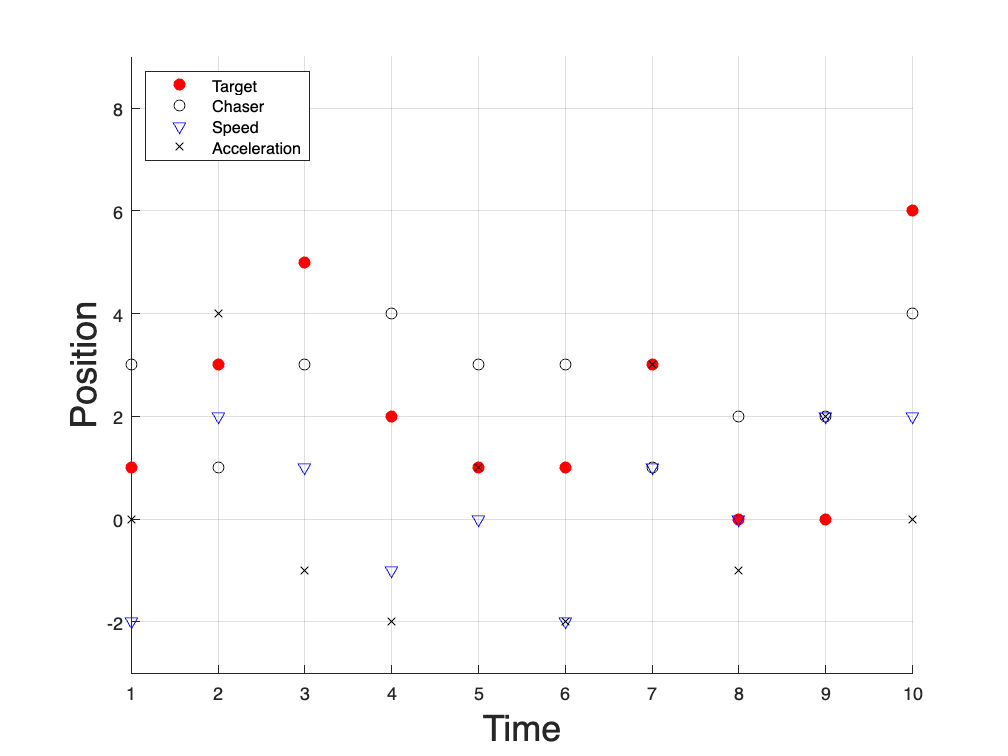

% number of instants
n = 10;
% Speed
v = [-2 2 1 -1 0 -2 1 0 2 2]; % last item not used in constraints
figure;
% title('1D Target Tracking');
hold on;  
% Target
plot(1:10,...
     [1 3 5 2 1 1 3 0 0 6],'.','markersize',20,'color','red');
% Chaser
plot(1:10,...
     [3 1 3 4 3 3 1 2 2 4],'o','color','black');
% Speed
plot(1:10,...
     v,'v','color','blue');
legend('Target','Chaser','Speed','Location','southeast')
% Acceleration
plot(1:10,...
     [0 v(2:end)-v(1:end-1)],'kx');
legend('Target','Chaser','Speed','Acceleration','Location','northwest')
ylim([-3 9])
yl = ylabel('Position');
set(yl, 'FontSize', 20) 
xl = xlabel('Time');
set(xl, 'FontSize', 20) 
% ylim([0 34]);
hold off;
grid on;
f = gcf;
cd '/Users/michelbarbeau/Dropbox/MyProjects/2024/D-Wave'
exportgraphics(f,'1DTargetTracking.png');

## 3D Sample Execution

Number of instants:  10

Deltas:

 [[ 0  0 -1  0  1 -1  1 -1  0  1]

 [ 1 -1 -1  1 -1  1  1  1  0  1]

 [-1 -1  0  1  1  0  1 -1  0 -1]]

Target positions:

 [[7 7 6 6 7 6 7 6 6 7]

 [6 5 4 5 4 5 6 7 7 8]

 [4 5 5 6 7 7 8 7 7 6]]

Info: {'constraint_labels': ['xmin_0', 'xmin_2', 'pz_5', 'px_4', 'xmax_0', 'px_8', 'pz_3', 'py_2', 'xmax_2', 'px_3', 'pz_6', 'px_7', 'xmin_3', 'xmin_8', 'py_0', 'xmax_6', 'px_6', 'py_4', 'pz_0', 'xmin_1', 'xmax_3', 'xmax_7', 'py_3', 'py_6', 'px_5', 'pz_8', 'py_8', 'xmin_4', 'xmax_8', 'py_1', 'xmin_6', 'xmin_9', 'pz_1', 'px_2', 'px_0', 'xmin_5', 'xmin_7', 'px_1', 'py_7', 'xmax_9', 'pz_2', 'pz_7', 'xmax_1', 'pz_4', 'xmax_4', 'xmax_5', 'py_5'], 'qpu_access_time': 32087, 'charge_time': 5000000, 'run_time': 5433369, 'problem_id': '6ba40bb7-6369-43cc-82af-2c29e05737c1'}

Sample: {'vx_0': 0.0, 'vx_1': -6.0, 'vx_2': -7.0, 'vx_3': 0.0, 'vx_4': 0.0, 'vx_5': -1.0, 'vx_6': 0.0, 'vx_7': 2.0, 'vx_8': -2.0, 'vx_9': -3.0, 'vy_0': -1.0, 'vy_1': 1.0, 'vy_2': 0.0, 'vy_3': 0.0, 'vy_4': 1.0, 'vy_5': -1.0, 'vy_6': 1.0, 'vy_7': 1.0, 'vy_8': 1.0, 'vy_9': 3.0, 'vz_0': 1.0, 'vz_1': 0.0, 'vz_2': 0.0, 'vz_3': 1.0, 'vz_4': 1.0, 'vz_5': 0.0, 'vz_6': 0.0, 'vz_7': -1.0, 'vz_8': -1.0, 'vz_9': -1.0, 'x_0': 7.0, 'x_1': 7.0, 'x_2': 7.0, 'x_3': 7.0, 'x_4': 7.0, 'x_5': 7.0, 'x_6': 6.0, 'x_7': 6.0, 'x_8': 8.0, 'x_9': 6.0, 'y_0': 5.0, 'y_1': 4.0, 'y_2': 5.0, 'y_3': 5.0, 'y_4': 5.0, 'y_5': 6.0, 'y_6': 5.0, 'y_7': 6.0, 'y_8': 7.0, 'y_9': 8.0, 'z_0': 5.0, 'z_1': 6.0, 'z_2': 6.0, 'z_3': 6.0, 'z_4': 7.0, 'z_5': 8.0, 'z_6': 8.0, 'z_7': 8.0, 'z_8': 7.0, 'z_9': 6.0}

Tracking score: 45.0

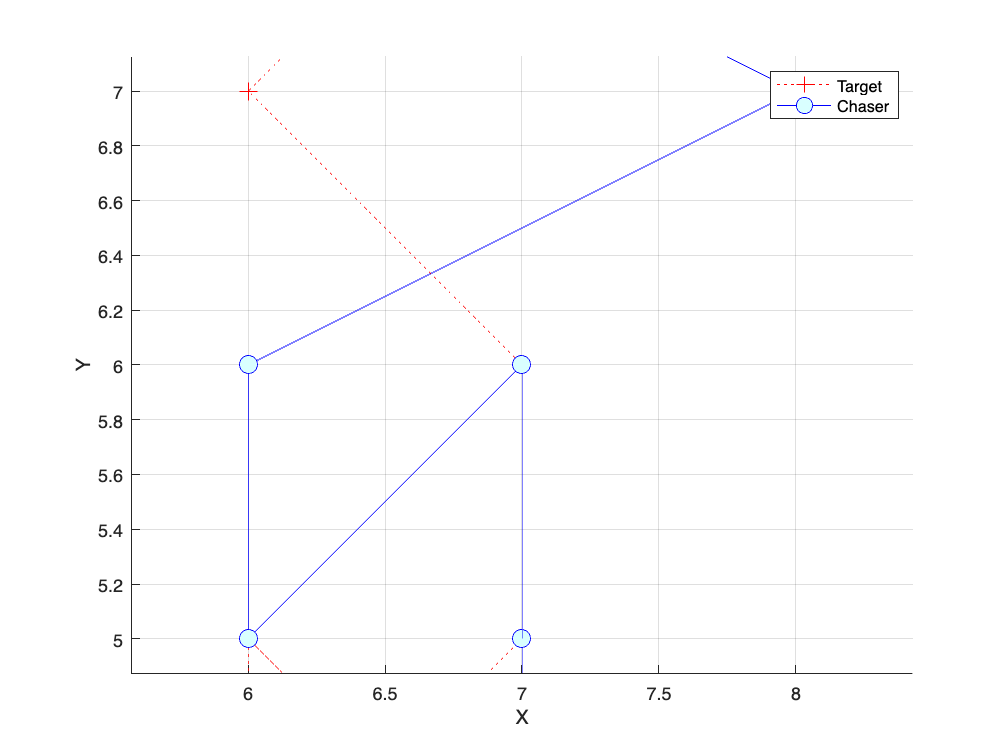

clear;
figure;
% Target positions
X = [7 7 6 6 7 6 7 6 6 7];
Y = [6 5 4 5 4 5 6 7 7 8];
Z = [4 5 5 6 7 7 8 7 7 6];
hold on;  
plot3(X,Y,Z,':+','Color','r','MarkerSize',10,...
    'MarkerFaceColor','red')
% Chaser position
CX = [7 7 7 7 7 7 6 6 8 6];
CY = [5 4 5 5 5 6 5 6 7 8];
CZ = [5 6 6 6 7 8 8 8 7 6];
plot3(CX,CY,CZ,'-o','Color','b','MarkerSize',10,...
     'MarkerFaceColor','#D9FFFF')
legend('Target','Chaser');
hold off;
grid on
axis equal
xlabel('X')
ylabel('Y')
zlabel('Z')
zlim([4 8.5])
cd '/Users/michelbarbeau/Dropbox/MyProjects/2024/D-Wave'
f = gcf;
exportgraphics(f,'3DTargetTracking.png');

## 3D Target Tracking -  Chaser-Target Separation Distance

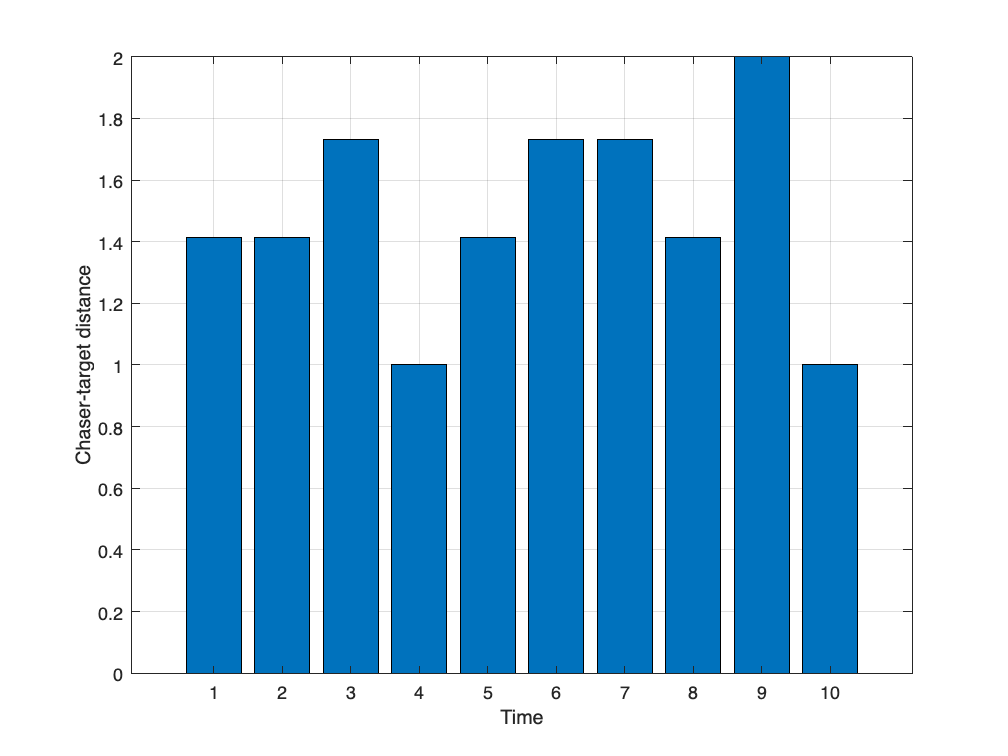

dx = zeros(1, length(X));
for i=1:length(dx);
    dx(i) = sqrt( (X(i)-CX(i))^2+(Y(i)-CY(i))^2+(Y(i)-CY(i))^2 );
end
figure
bar(dx)
xlabel('Time')
ylabel('Chaser-target distance')
grid on
cd '/Users/michelbarbeau/Dropbox/MyProjects/2024/D-Wave'
f = gcf;
exportgraphics(f,'3DChaserTargetDistance.png');

## **Run Time Statistics**

**Data March 10, 2024**

### **Quantum Optimization 3D **

**Number of points is **`(i + ``1``) * ``100. Every pair is 'run_time' and 'qpu_access_time' `**(microseconds)**`.`

i:  0 

5163726 32073  

5194316 16019  

5002378 16018  

5204517 32050  

5173784 32073  

5154063 32044  

5337635 32061  

5160522 32046  

5267645 32083  

5167267 32043  

RTAverage:  5182585.3 RQPUAverage:  28851.0 

i:  1 

5203297 32052  

5448113 32102  

5182753 32072  

5132333 32055  

5184066 32043  

5337604 32064  

5190912 32035  

5206216 32082  

5157409 32035  

5183266 32039  

RTAverage:  5222596.9 RQPUAverage:  32057.9 

i:  2 

5165852 32029  

5272708 32039  

5181485 32028  

5159045 32042  

5173623 32039  

5220126 32028  

5182760 32029  

5167582 32041  

5141463 32045  

5314126 32046  

RTAverage:  5197877.0 RQPUAverage:  32036.6 

i:  3 

5149829 32052  

5122490 32045  

5147109 32038  

5121492 32034  

5125326 32039  

5170109 32070  

5201203 32029  

5152633 32067  

5184305 32032  

5320559 32042  

RTAverage:  5169505.5 RQPUAverage:  32044.8 

i:  4 

5001380 16008  

5190140 16020  

5140014 32044  

5108881 32043  

5149641 32069  

5158301 32034  

5131294 32046  

5338182 32078  

5217279 32080  

5169012 32040  

RTAverage:  5160412.4 RQPUAverage:  28846.2 

i:  5 

5174867 32060  

5111463 32045  

5222782 32068  

5138731 32047  

5137774 32041  

5254934 32046  

5253308 32048  

5201944 32046  

5167071 32042  

5176080 32046  

RTAverage:  5183895.4 RQPUAverage:  32048.9 

i:  6 

5169108 32044  

5210335 32047  

5145408 32027  

5190119 32033  

5152922 32046  

5342695 32057  

5130283 32076  

5197511 32029  

5194077 32077  

5161065 32064  

RTAverage:  5189352.3 RQPUAverage:  32050.0 

i:  7 

5166014 32028  

5116526 32048  

5189000 32050  

5191108 32048  

5202898 32044  

5129973 32044  

5127692 32045  

5155383 32050  

5189333 32050  

5198147 32031  

RTAverage:  5166607.4 RQPUAverage:  32043.8 

i:  8 

5157175 32039  

5177212 32036  

5123934 32049  

5197005 32034  

5320313 32029  

5079005 0  

5003112 16022  

5236918 32030  

5162024 32039  

5002906 16017  

RTAverage:  5145960.4 RQPUAverage:  25629.5 

i:  9 

5326866 32045  

5139101 32042  

5210366 32016  

5159554 32052  

5158075 32049  

5099552 32043  

5243772 32035  

5192010 32077  

5215123 32046  

5299533 32051  

RTAverage:  5204395.2 RQPUAverage:  32045.6 

**Summary**

RT Averages: [5182585.3 5222596.9 5197877.  5169505.5 5160412.4 5183895.4 5189352.3

 5166607.4 5145960.4 5204395.2] 

QPU Averages: [28851.  32057.9 32036.6 32044.8 28846.2 32048.9 32050.  32043.8 25629.5

 32045.6] 

### Classical Optimization 3D

**Number of points is **`(i + 1) * 100. Every point is 'run_time' ``(`**seconds)**`.`

`i:  0  `

`16.527743700000002   17.103310749000002   16.401153494   16.64637464499998   16.72596089000001   16.32496523200001   16.444352444000003   16.76032208999999   17.79908537   16.895830444000012   `

`Average:  16.7629099058  `

`i:  1  `

`100.55113033099997   101.99184734399995   103.39291746399999   102.03832805900004   101.788133991   101.50723764999998   104.63937119399998   101.06950701799997   103.00000580799997   104.06715668399988   `

`Average:  102.40456355429997  `

`i:  2  `

`315.91783386299994   315.58303845600017   311.561151635   314.7404536670001   314.01627915100016   313.2410824950002   310.0567629970001   307.7261469079999   324.4356787439997   322.56122711199987   `

`Average:  314.98396550280006  `

`i:  3  `

`748.7533462660003   754.3083918570001   755.5214846750005   754.1093404629992   762.34387771   772.122680651999   773.5168428039997   773.4504516880006   772.5488392930001   835.6380418789995   `

`Average:  770.2313297286998  `

`i:  4  `

`1676.3255898450006   1690.6311318919998   1681.9067174339998   1698.6427400479988   1697.7595190110005   1690.6797501460023   1521.156864872999   1540.537699911998   1638.4785034650013   1624.490847268   `

`Average:  1646.0609363894  `

`i:  5  `

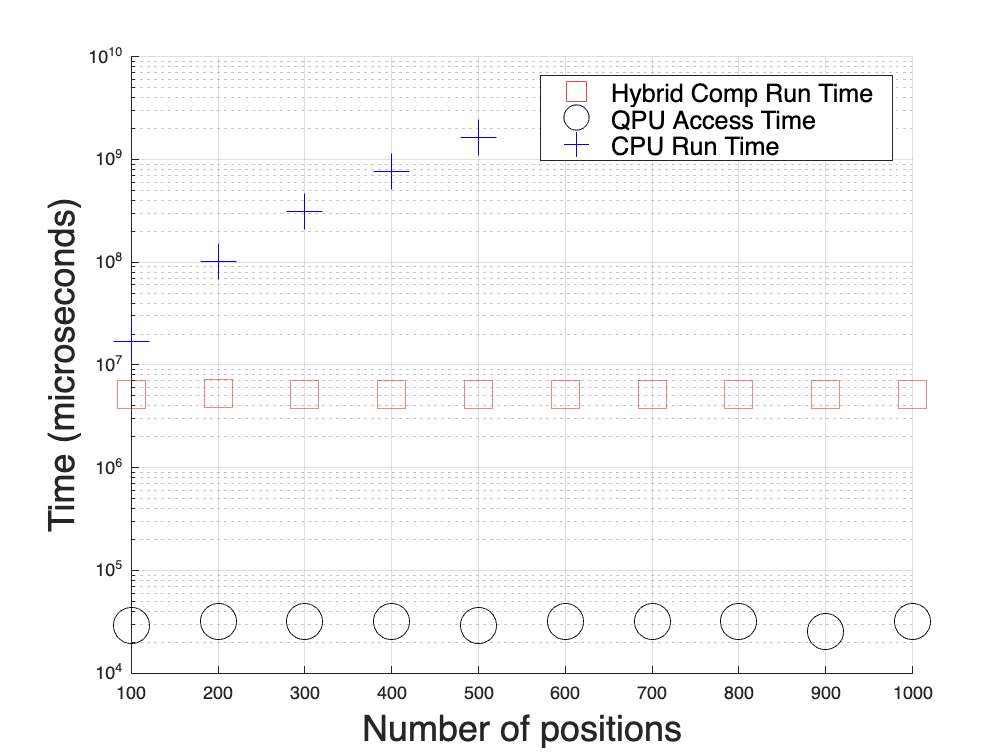

clear;
figure;
hold on; 
%%%% Hybrid computing run time (microseconds)
RT = [5182585.3 5222596.9 5197877.  5169505.5 5160412.4 5183895.4 5189352.3 5166607.4 5145960.4 5204395.2];
% Plot hybrid computing run time
plot(100:100:length(RT)*100,RT,'s','MarkerSize',20,'color','red');
%%%% QPU Access Time (milliseconds)
QT = [28851.  32057.9 32036.6 32044.8 28846.2 32048.9 32050.  32043.8 25629.5 32045.6 ]; 
% Plot QPU access time
plot(100:100:length(QT)*100,QT,'o','MarkerSize',20,'color','black');
%%% Classical CPU run time (originally in seconds, coverted in microseconds
%%% with the 1,000,000 factor
CPU = 1000000*[16.7629099058 102.40456355429997 314.98396550280006 770.2313297286998 1646.0609363894  ];
% Plot classical runtime
plot(100:100:length(CPU)*100, CPU,'+','MarkerSize',20,'color','blue');

legend({'Hybrid Comp Run Time','QPU Access Time','CPU Run Time'},'Location','best','FontSize',14)
yl = ylabel('Time (microseconds)');
set(yl, 'FontSize', 20) 
xl = xlabel('Number of positions');
set(xl, 'FontSize', 20) 
% ylim([0 34]);
hold off;
grid on;
set(gca, 'YScale', 'log')
cd '/Users/michelbarbeau/Dropbox/MyProjects/2024/D-Wave'
f = gcf;
exportgraphics(f,'3DRunTime.png');